# 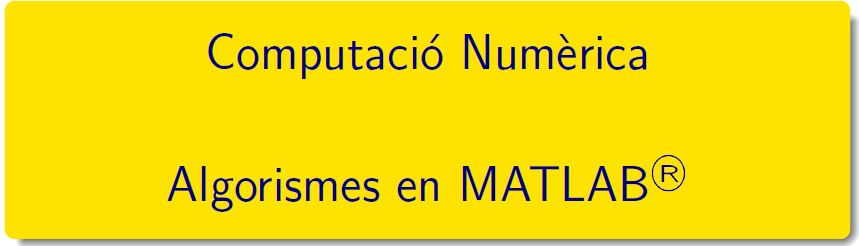

# Pràctica 2 - Activitat 1: Conceptes Bàsics (revisió pràctica 1)

`Document preparat per M. Àngela Grau Gotés, 22 de febrer de 2023`

## 1. Introducció a MATLAB

[ Cleve’s Corner: Cleve Moler on Mathematics and Computing](https://blogs.mathworks.com/cleve/)

[A Brief History of MATLAB](https://es.mathworks.com/company/newsletters/articles/a-brief-history-of-matlab.html?s_tid=srchtitle)

### Practiquem les funcions

#### Exercici 6, pàgina 23. [Funcions anònimes](https://es.mathworks.com/help/matlab/matlab_prog/anonymous-functions.html)

`h = @(``arglist``)``anonymous_function`

**6**  Avalueu les funcions  $\displaystyle f(x)=\sqrt{x^2+1}-1\,,\quad\quad
g(x)=x^2/{\left( \sqrt{x^2+1}+1\right) }$ per a la successió de valors de $x_n= 8^{-n}\,,\ n\geq 1\,.$ 

Encara que $f(x)=g(x)$, l'ordinador dóna resultats diferents. Feu un joc de proves prenent $2^{-n},5^{-n},7^{-n},10^{-n}, \dots$

Quins resultats són de fiar i quins no? Per què?  Expliqueu la vostra resposta

clearvars
format shortG
n = 0:15;
x = 8.^(-n);
f = @(x)sqrt(x.^2+1)-1;
g = @(x)x.^2./(sqrt(x.^2+1)+1);
r = [n; x; f(x); g(x)]'

r =             0            1      0.41421      0.41421
            1        0.125    0.0077822    0.0077822
            2     0.015625   0.00012206   0.00012206
            3    0.0019531   1.9073e-06   1.9073e-06
            4   0.00024414   2.9802e-08   2.9802e-08
            5   3.0518e-05   4.6566e-10   4.6566e-10
            6   3.8147e-06    7.276e-12    7.276e-12
            7   4.7684e-07   1.1369e-13   1.1369e-13
            8   5.9605e-08   1.7764e-15   1.7764e-15
            9   7.4506e-09            0   2.7756e-17


#### Exercici 8, pàgina 23. [Funcions en Live script](https://es.mathworks.com/help/matlab/ref/function.html)

`function f = nom_fun(``arglist``)`

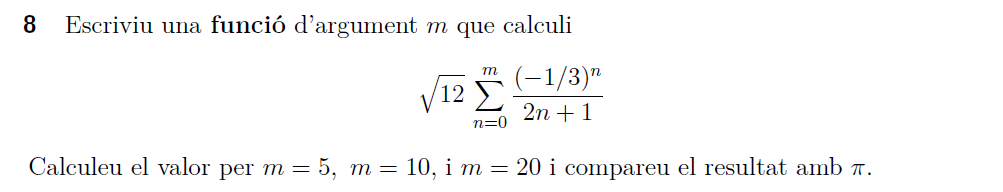

f5 = funcio(5)

f5 =        3.1413


abs(f5 - pi)

ans =    0.00028387


f10 = funcio(10)

f10 =        3.1416


abs(f10 - pi)

ans =    6.5091e-07


f20 = funcio(20)

f20 =        3.1416


abs(f20 - pi)

ans =     5.842e-12


## 2. Algorismes: Estabilitat numèrica i problemes ben condicionats

**(ja eren al document prac01)**

#### Exercici 11, pàgina 23. **Càlcul d'integrals per recurrència**	

	Per calcular les integrals$\displaystyle I_{n}=\int_{0}^{1} x^n e^{x-1}dx\,,\quad n\ge~1\,,$ 	dispossem de dos mètodes iteratius diferents:

	            
$$$$\begin{array}{llrr}
	\text{ a)}\quad I_{n-1}&=\displaystyle\frac{1-I_n}{n}, & n\ge 2 &{\rm\ on\ }I_{50}=0\,,\\  & & & \\
	\text{ b)}\quad I_n&=1-nI_{n-1}, & n\ge 2 &{\rm\ on\ }I_1=1/e\,.
	\end{array}$$$$


	Calculeu $$I_{30}$\,$ pels dos mètodes. Obteniu els mateixos resultats ? Sabrieu donar una explicació?

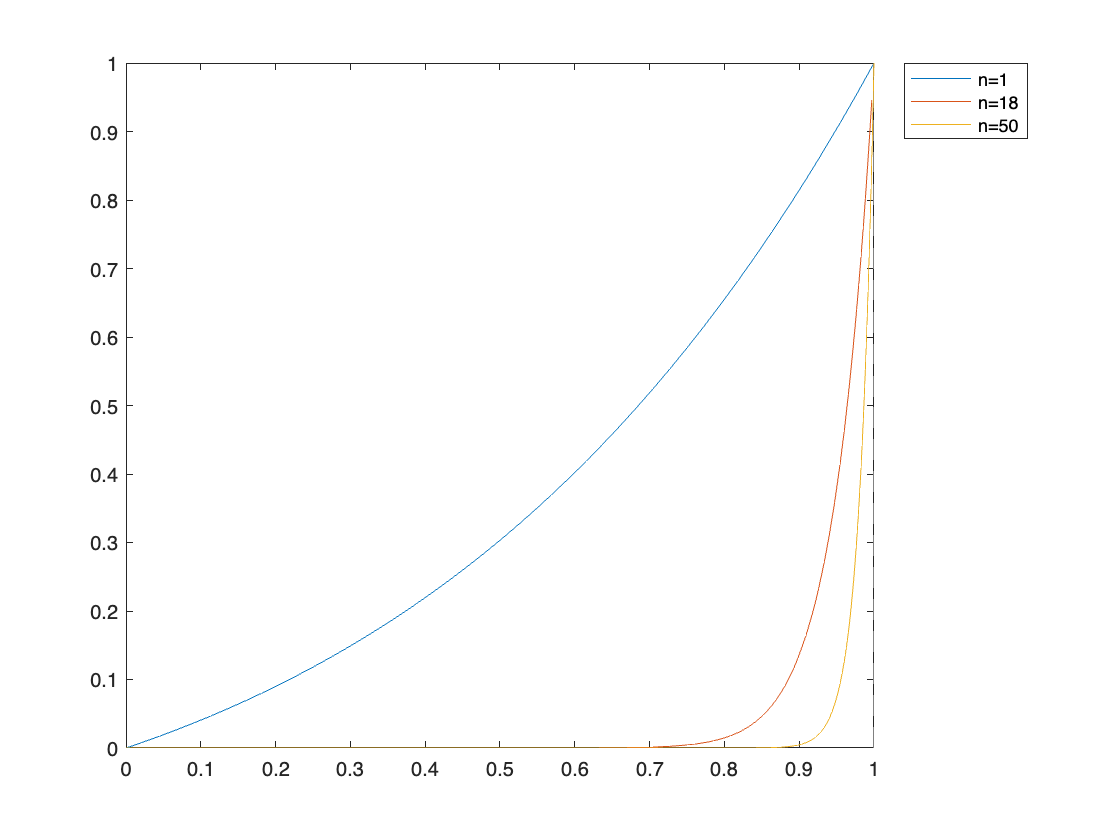

clearvars
F = @(x,n)x.^n.*exp(x-1);
fplot({@(x)F(x,1),@(x)F(x,18),@(x)F(x,50)},[0,1])
legend('n=1','n=18','n=50','location','bestoutside')

- apartat a)

J(50) = 0;

for k = 50:-1:2
    J(k-1) = (1 - J(k))/k;
end

[50:-1:1;J(50:-1:1)]'

ans =            50            0
           49         0.02
           48         0.02
           47     0.020417
           46     0.020842
           45     0.021286
           44     0.021749
           43     0.022233
           42     0.022739
           41     0.023268


- apartat b)

I(1) = 1/exp(1);
for n = 2:30
    I(n) = 1 - n*I(n-1);
end
[1:30;I]'

ans =             1      0.36788
            2      0.26424
            3      0.20728
            4      0.17089
            5      0.14553
            6       0.1268
            7      0.11238
            8      0.10093
            9     0.091612
           10     0.083877


- valor aproximat per integració numèrica

for n=1:30
    valor(n) = integral(@(x)F(x,n),0,1);
end

- Taula comparativa de resultats

[1:30; I; valor; J(1:30)]'

ans =             1      0.36788      0.36788      0.36788
            2      0.26424      0.26424      0.26424
            3      0.20728      0.20728      0.20728
            4      0.17089      0.17089      0.17089
            5      0.14553      0.14553      0.14553
            6       0.1268       0.1268       0.1268
            7      0.11238      0.11238      0.11238
            8      0.10093      0.10093      0.10093
            9     0.091612     0.091612     0.091612
           10     0.083877     0.083877     0.083877


- Taula comparativa d'errors

[1:30; abs(I-valor); abs(J(1:30)-valor)]'

ans =             1   5.5511e-17   5.5511e-17
            2   5.5511e-17   5.5511e-17
            3   1.1102e-16   5.5511e-17
            4   2.7756e-16            0
            5   1.4988e-15   2.7756e-17
            6   8.9373e-15            0
            7   6.2658e-14   1.3878e-17
            8   5.0113e-13            0
            9   4.5102e-12   1.3878e-17
           10   4.5101e-11   1.3878e-17


## 3. Pràctica

#### Exercici 10, pàgina 23.  Sumar sèrie $e^x$

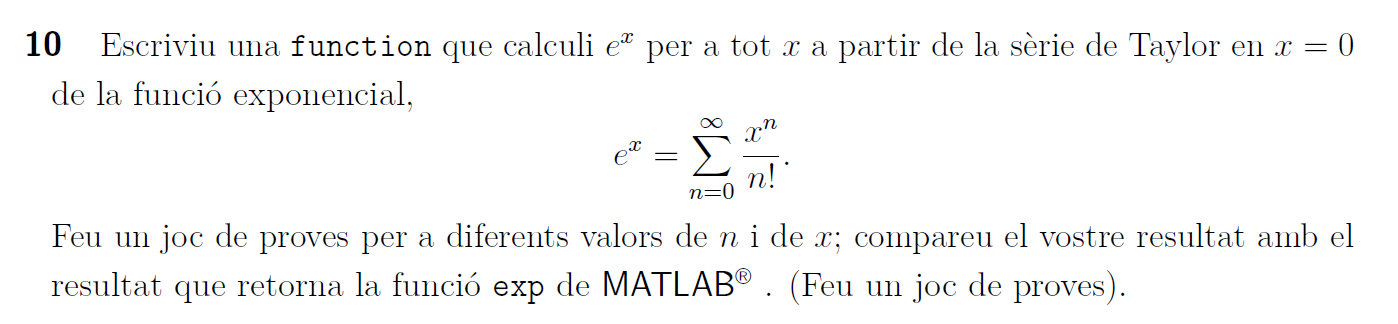     

#### Exercici 12, pàgina 23.  Sumar sèrie $\sin(x)$

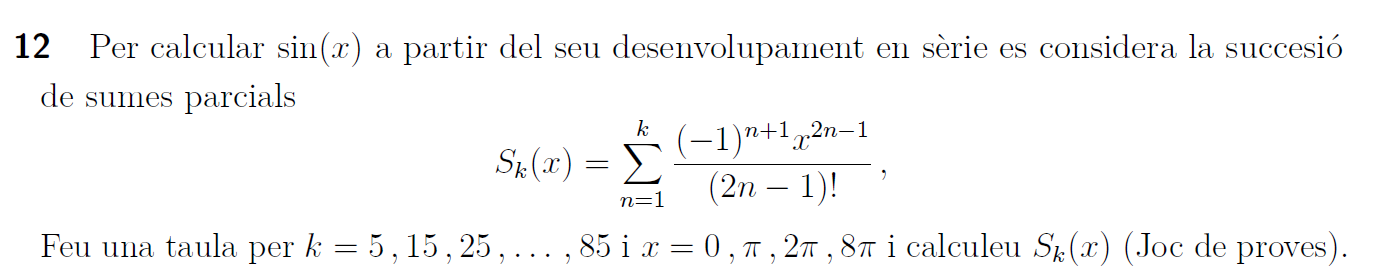

function f = funcio(m)
    sum = 0;
    for n = 0:m
        sum = sum + ((-1/3).^n)./(2*n + 1);
    end
    f = sqrt(12)*sum;
end

`Document preparat per M. Àngela Grau Gotés, 22 de febrer de 2023`